# **Lec15 | Numerical Differentiation (1) [ALL CORRECT]**

### **Just transform math expressions into MATLAB code**

Compute forward and backward difference approximations of O(h) and O(h^2), and central difference approximations of O(h^2) and O(h^4) for the first derivative of y = -0.1x^4 - 0.15x^3 - 0.5x^2 - 0.25x + 1.2 at x = 0.5 using a value of h = 0.25. 

Estimate the true percent relative error for each approximation.

f = @(x) -0.1*x.^4 - 0.15*x.^3 - 0.5*x.^2 - 0.25*x + 1.2

f = 値をもつ function_handle :
    @(x)-0.1*x.^4-0.15*x.^3-0.5*x.^2-0.25*x+1.2


True value *(analytic; differentiate once)*

% given in the question
xi = 0.5

xi = 0.5000

h = 0.25 % step size

h = 0.2500


df = @(x) -0.4*x.^3 - 0.45*x.^2 - x - 0.25 % hand-calculated

df = 値をもつ function_handle :
    @(x)-0.4*x.^3-0.45*x.^2-x-0.25


diff_xi_true = df(xi) % true first derivative

diff_xi_true = -0.9125

# Vanilla

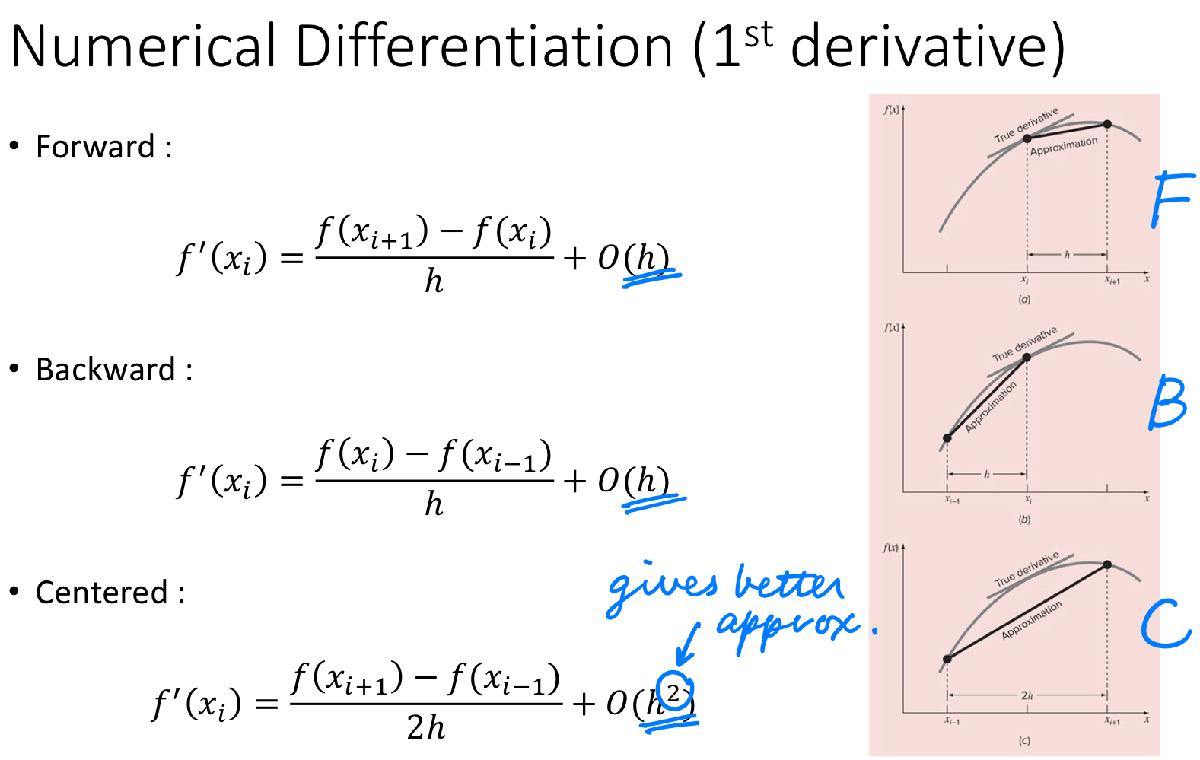 *(Lec15 p.7)*

xi1 = xi + h; % x of i + 1
xi_1 = xi - h; % x of i - 1

**Forward difference** approximation of the first derivative O(h)

forward_Oh = (f(xi1) - f(xi)) / h

forward_Oh = -1.1547

err_forward_Oh = ((diff_xi_true - forward_Oh) / diff_xi_true) * 100

err_forward_Oh = -26.5411

**Backward difference **approximation of the first derivative O(h)

backward_Oh = (f(xi) - f(xi_1)) / h

backward_Oh = -0.7141

err_backward_Oh = ((diff_xi_true - backward_Oh) / diff_xi_true) * 100

err_backward_Oh = 21.7466

**Centered difference **approximation of the first derivative O(h^2)

centered_Oh2 = (f(xi1) - f(xi_1)) / (2*h)

centered_Oh2 = -0.9344

err_centered_Oh2 = ((diff_xi_true - centered_Oh2) / diff_xi_true) * 100

err_centered_Oh2 = -2.3973

# High Accuracy

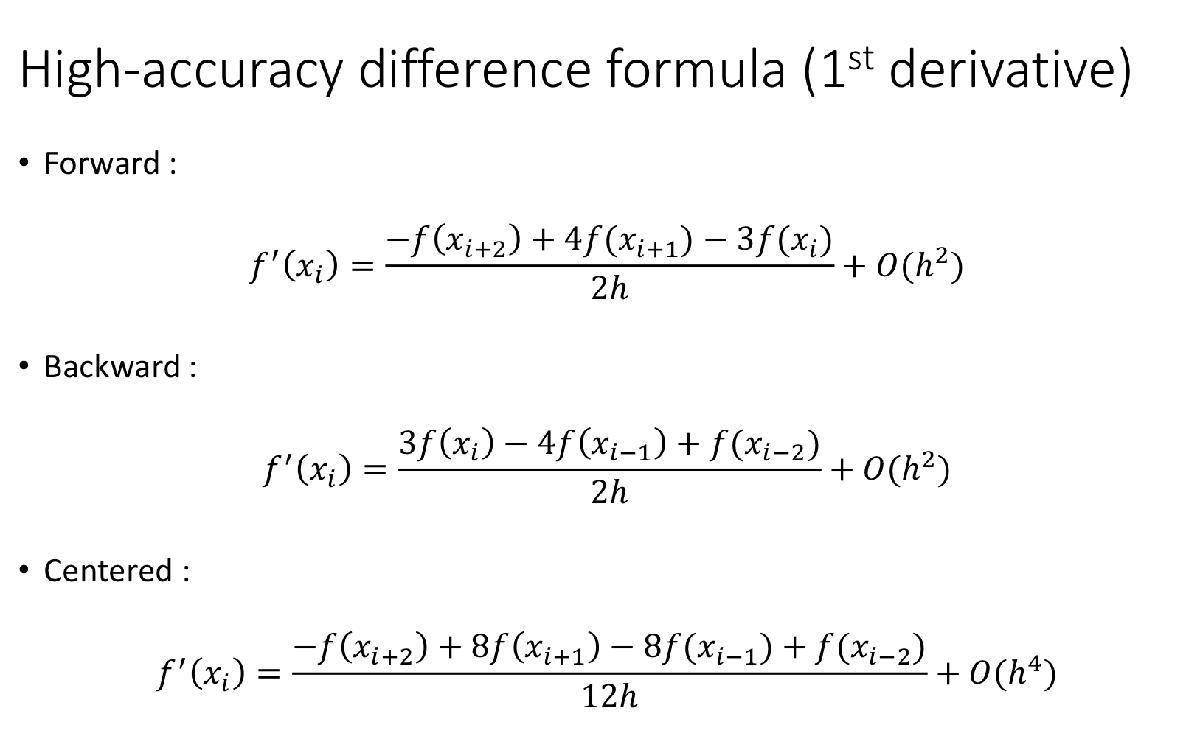 *(Lec15 p.15)*

xi2 = xi + (2*h); % x of i + 2
xi_2 = xi - (2*h); % x of i - 2

**Forward difference **approximation of the first derivative O(h^2)

forward_Oh2 = (-f(xi2) + (4*f(xi1)) - (3*f(xi))) / (2*h)

forward_Oh2 = -0.8594

err_forward_Oh2 = ((diff_xi_true - forward_Oh2) / diff_xi_true) * 100

err_forward_Oh2 = 5.8219

**Backward difference **approximation of the first derivative O(h^2)

backward_Oh2 = ((3*f(xi)) - (4*f(xi_1)) + f(xi_2)) / (2*h)

backward_Oh2 = -0.8781

err_backward_Oh2 = ((diff_xi_true - backward_Oh2) / diff_xi_true) * 100

err_backward_Oh2 = 3.7671

**Centered difference **approximation of the first derivative O(h^4)

centered_Oh4 = (-f(xi2) + (8*f(xi1)) - (8*f(xi_1)) + f(xi_2)) / (12*h)

centered_Oh4 = -0.9125

err_centered_Oh4 = ((diff_xi_true - centered_Oh4) / diff_xi_true) * 100

err_centered_Oh4 = -2.4334e-14